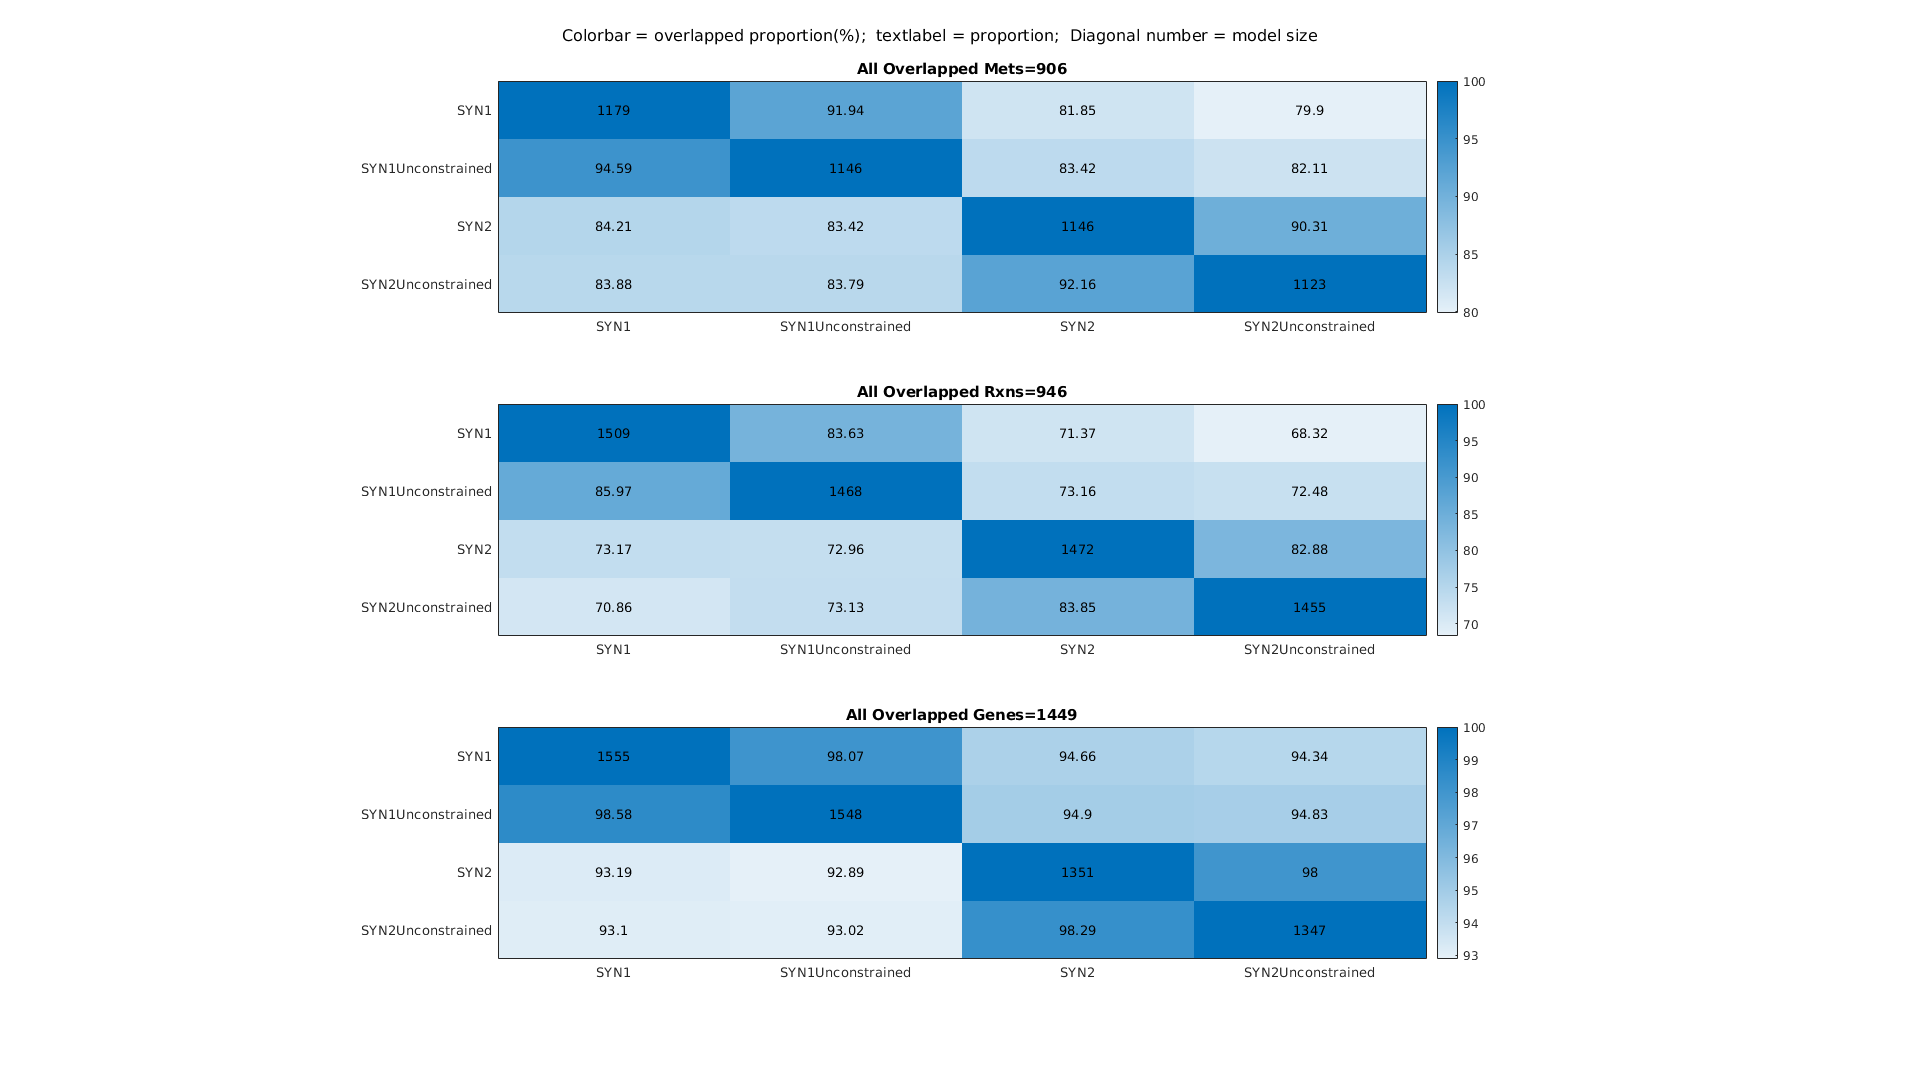

% load old and new models
baseFolderOld='~/drive/bioenergeticsPD/results/modelGeneration/models';
param.tissueSpecificSolver='fastCore';
switch param.tissueSpecificSolver
    case 'fastCore'
        baseFolderNew='~/drive/bioenergeticsPD/fromXi/model/fastcore';
    case 'thermoKernel'
        baseFolderNew='~/drive/bioenergeticsPD/fromXi/model/thermokernel';
end


% SYN models
% old with constrain
load([baseFolderOld filesep 'neuron/synaptic/SYN1.mat'])
SYN.SYN1=SYN1;
SYN.SYN1.genes = regexprep(SYN.SYN1.genes, '\.\d', '');
% old without constrain
load([baseFolderOld filesep 'neuron/synaptic/unconstrained/SYN1_UNCONSTRAINED.mat'])
SYN.SYN1Unconstrained=SYN1_UNCONSTRAINED;
SYN.SYN1Unconstrained.genes = regexprep(SYN.SYN1Unconstrained.genes, '\.\d', '');
% new with constrain
load([baseFolderNew filesep 'synaptic_model/synaptic_model.mat'])
SYN.SYN2=GeneratedModel;
% new without constrain
load([baseFolderNew filesep 'synaptic_unconstrained_model/synaptic_unconstrained_model.mat'])
SYN.SYN2Unconstrained=GeneratedModel;

%compare
[overlapResults,statistic]=compareXomicsModels(SYN,0);
plotOverlapResults(overlapResults,statistic)

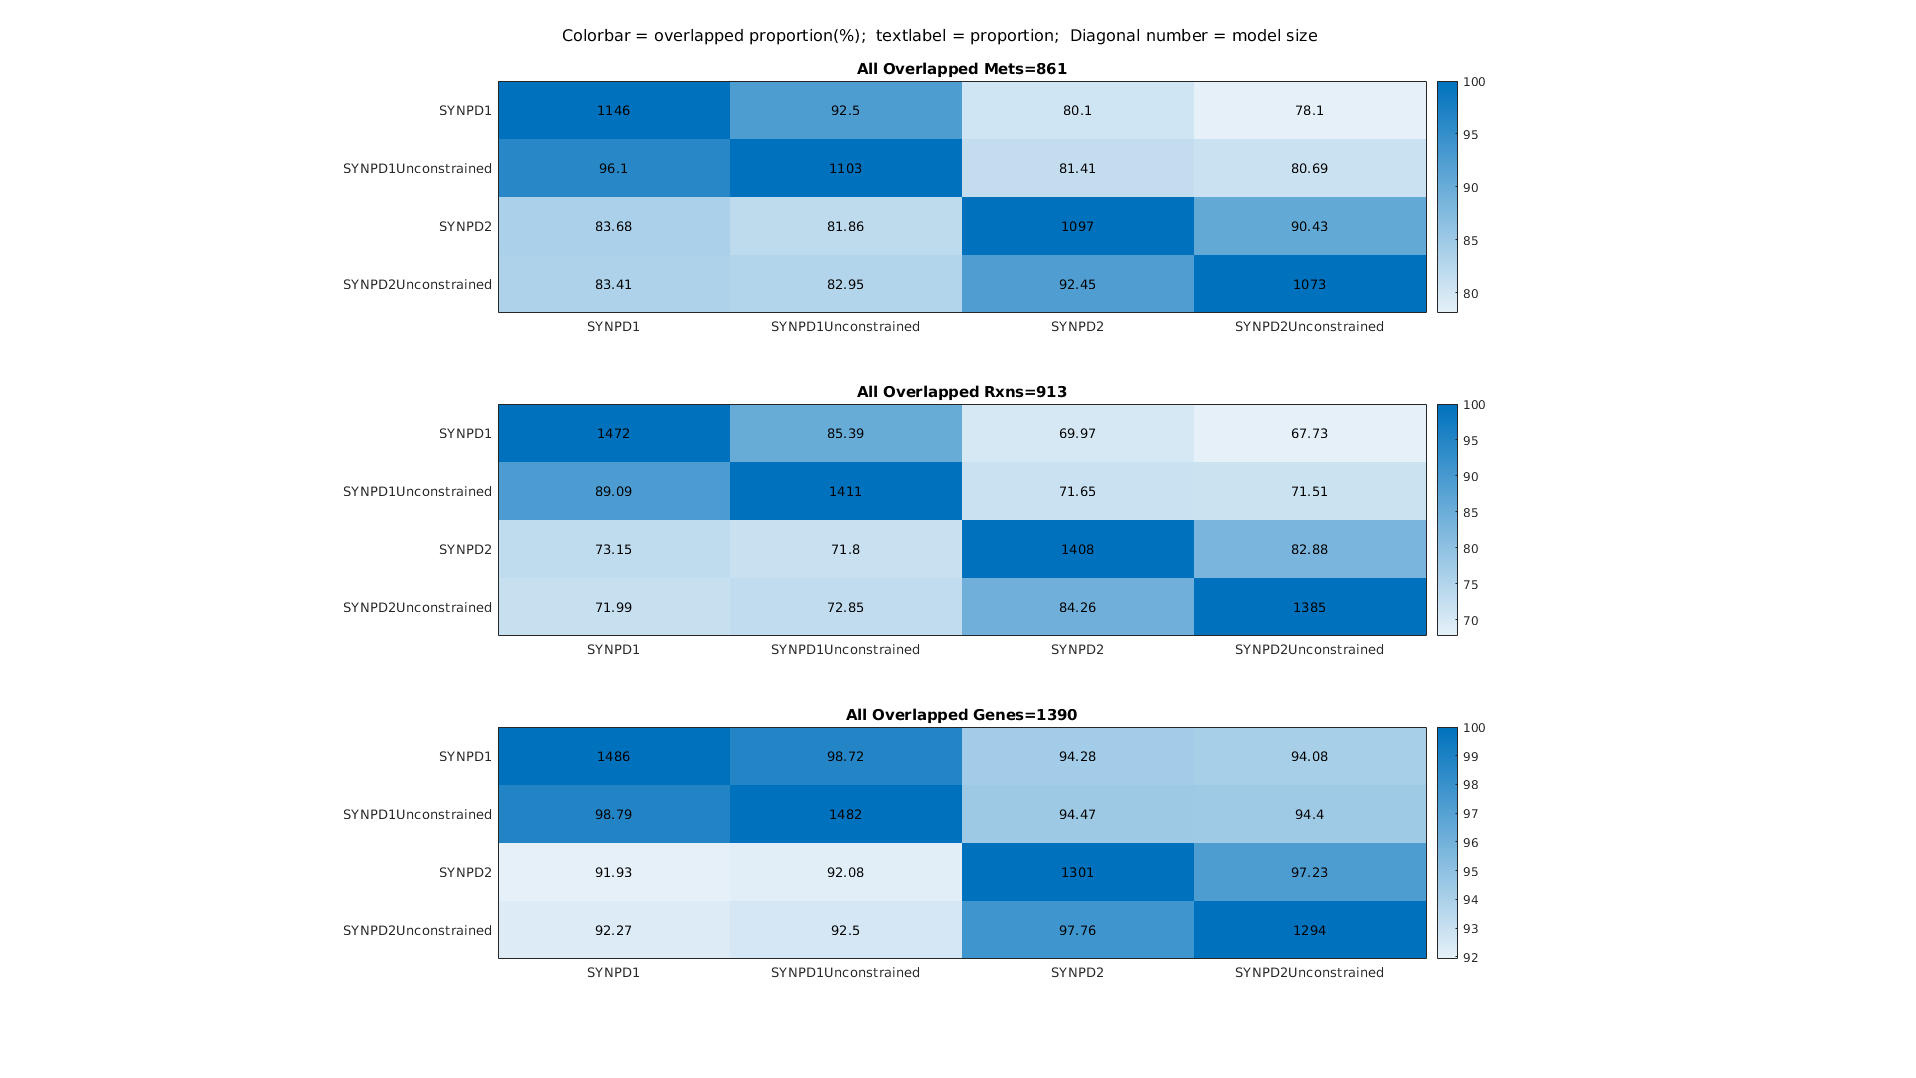

% SYNPD model
% old PD model with constrain
load([baseFolderOld filesep 'neuron/synaptic/SYNPD1.mat'])
SYNPD.SYNPD1=SYNPD1;
SYNPD.SYNPD1.genes= regexprep(SYNPD.SYNPD1.genes, '\.\d', '');
% old PD model without constrain
load([baseFolderOld filesep 'neuron/synaptic/unconstrained/SYNPD1_UNCONSTRAINED.mat'])
SYNPD.SYNPD1Unconstrained=SYNPD1_UNCONSTRAINED;
SYNPD.SYNPD1Unconstrained.genes = regexprep(SYNPD.SYNPD1Unconstrained.genes, '\.\d', '');
% new PD model with constrain
load([baseFolderNew filesep 'synapticPD_model/synapticPD_model.mat'])
SYNPD.SYNPD2=GeneratedModel;
% new PD model without constrain
load([baseFolderNew filesep 'synapticPD_unconstrained_model/synapticPD_unconstrained_model.mat'])
SYNPD.SYNPD2Unconstrained=GeneratedModel;

clear SYN1 SYN1_UNCONSTRAINED SYNPD1 SYNPD1_UNCONSTRAINED GeneratedModel
%compare
[overlapResults,statistic]=compareXomicsModels(SYNPD,0);
plotOverlapResults(overlapResults,statistic)

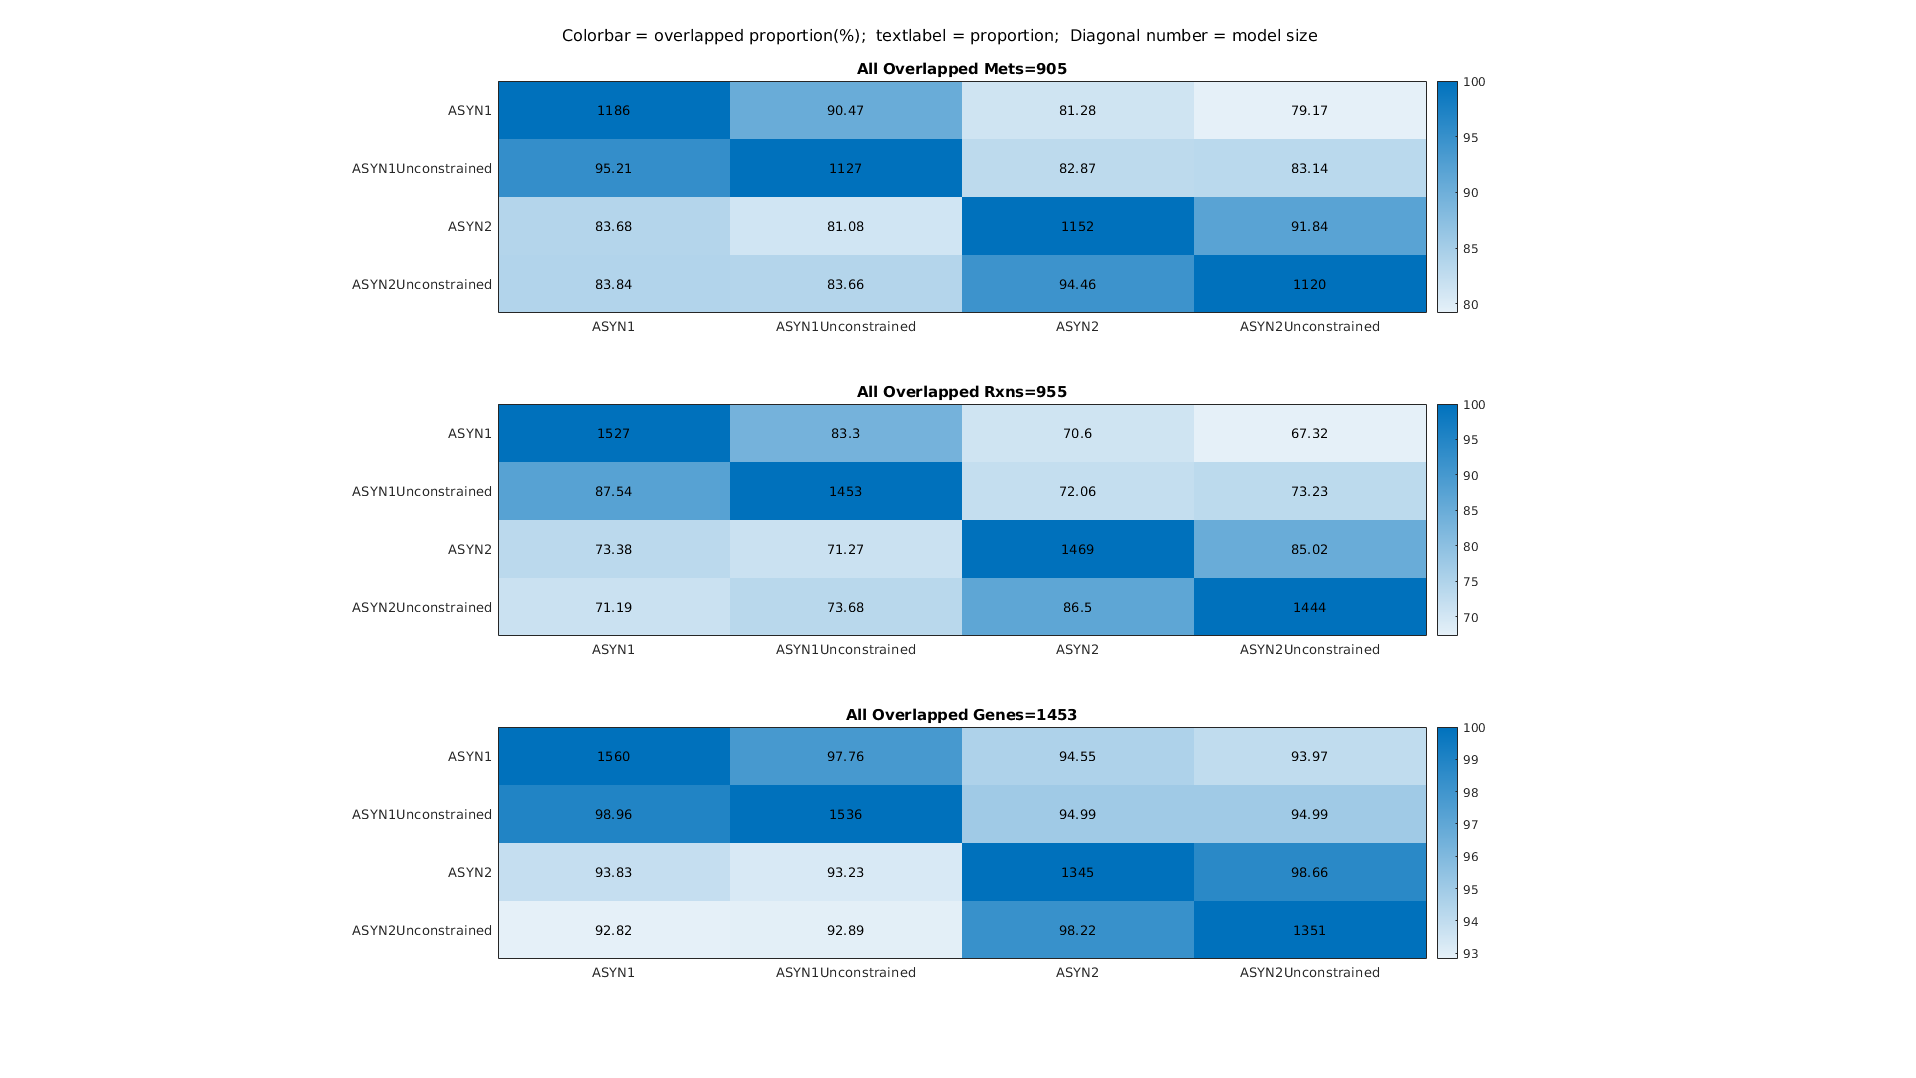

% nonSYN models
% old with constrain
load([baseFolderOld filesep 'neuron/non_synaptic/ASYN1.mat'])
ASYN.ASYN1=ASYN1;
ASYN.ASYN1.genes = regexprep(ASYN.ASYN1.genes, '\.\d', '');
% old without constrain
load([baseFolderOld filesep 'neuron/non_synaptic/unconstrained/ASYN1_UNCONSTRAINED.mat'])
ASYN.ASYN1Unconstrained=ASYN1_UNCONSTRAINED;
ASYN.ASYN1Unconstrained.genes = regexprep(ASYN.ASYN1Unconstrained.genes, '\.\d', '');
% new with constrain
load([baseFolderNew filesep 'nonsynaptic_model/nonsynaptic_model.mat'])
ASYN.ASYN2=GeneratedModel;
% new without constrain
load([baseFolderNew filesep 'nonsynaptic_unconstrained_model/nonsynaptic_unconstrained_model.mat'])
ASYN.ASYN2Unconstrained=GeneratedModel;

%compare
[overlapResults,statistic]=compareXomicsModels(ASYN,0);
plotOverlapResults(overlapResults,statistic)

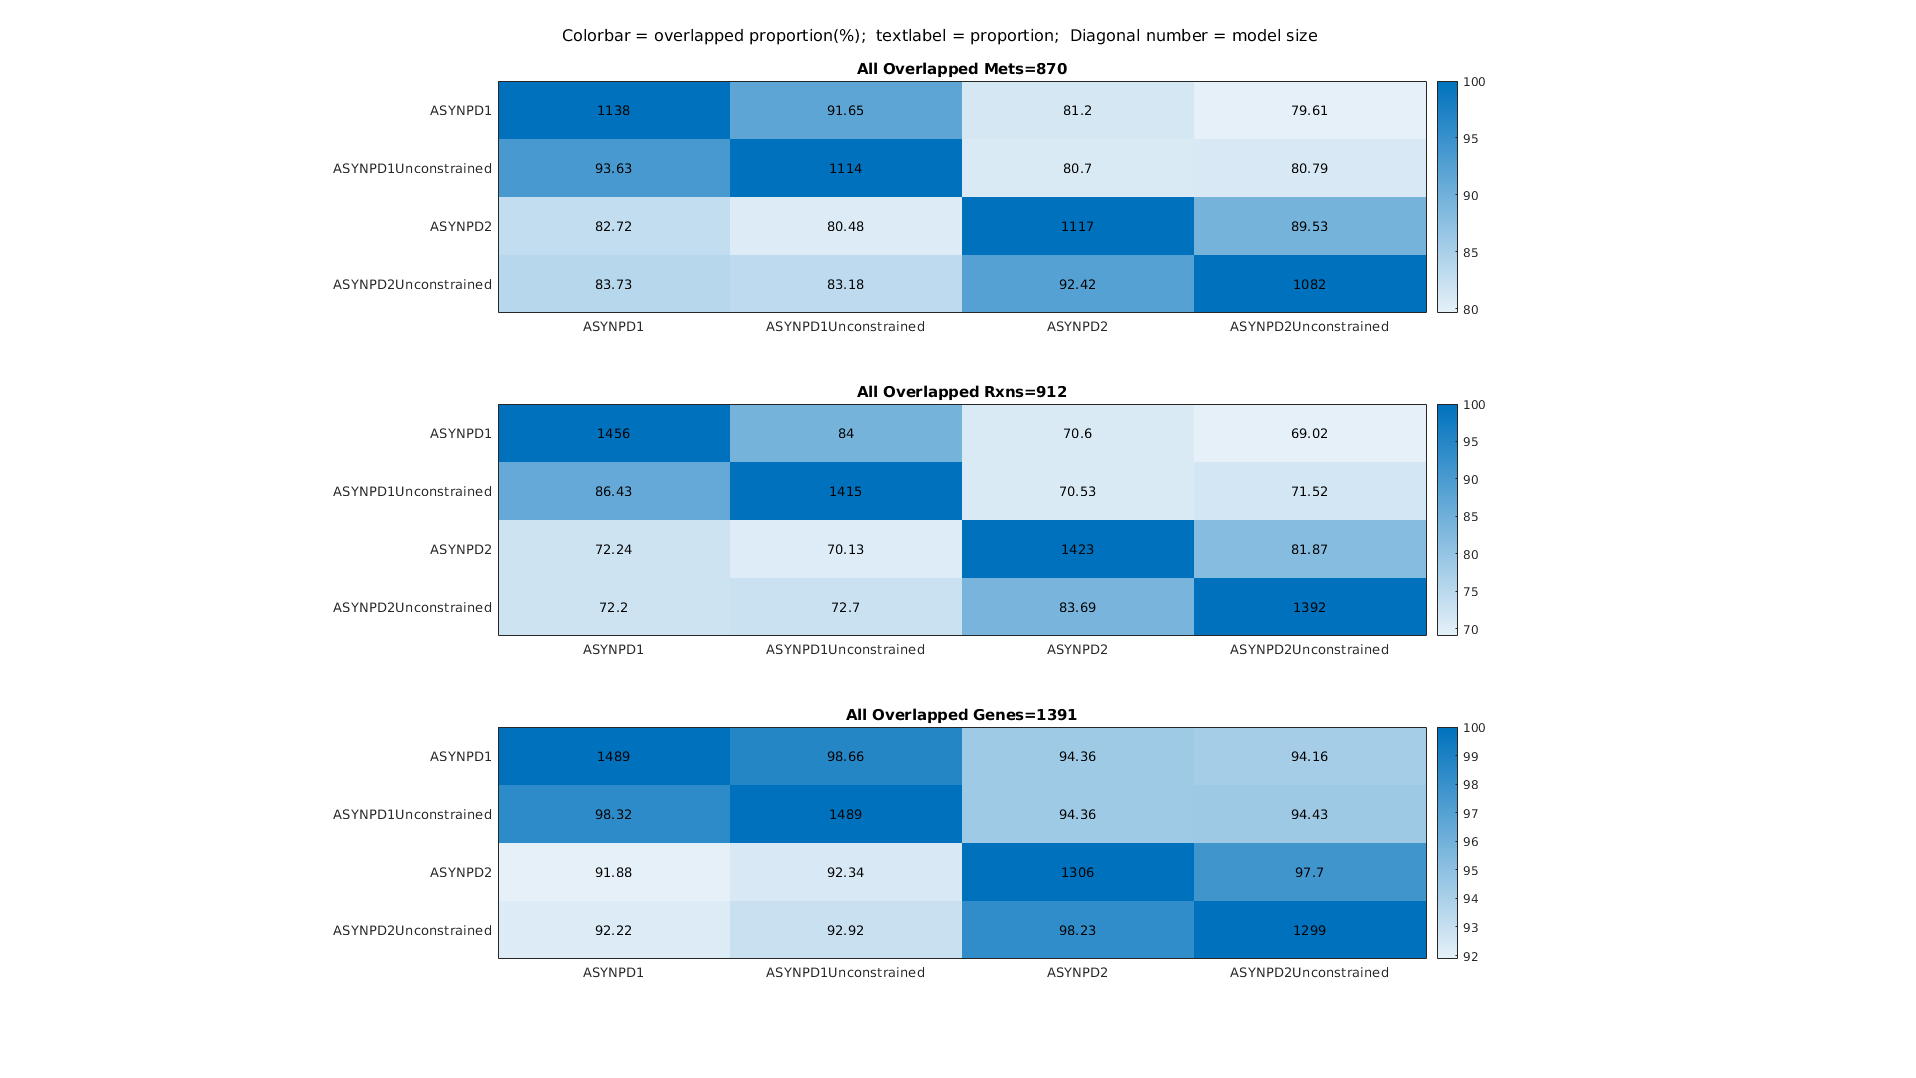


% nonSYNPD model
% old PD model with constrain
load([baseFolderOld filesep 'neuron/non_synaptic/ASYNPD1.mat'])
ASYNPD.ASYNPD1=ASYNPD1;
ASYNPD.ASYNPD1.genes= regexprep(ASYNPD.ASYNPD1.genes, '\.\d', '');
% old PD model without constrain
load([baseFolderOld filesep 'neuron/non_synaptic/unconstrained/ASYNPD1_UNCONSTRAINED.mat'])
ASYNPD.ASYNPD1Unconstrained=ASYNPD1_UNCONSTRAINED;
ASYNPD.ASYNPD1Unconstrained.genes = regexprep(ASYNPD.ASYNPD1Unconstrained.genes, '\.\d', '');
% new PD model with constrain
load([baseFolderNew filesep 'nonsynapticPD_model/nonsynapticPD_model.mat'])
ASYNPD.ASYNPD2=GeneratedModel;
% new PD model without constrain
load([baseFolderNew filesep 'nonsynapticPD_unconstrained_model/nonsynapticPD_unconstrained_model.mat'])
ASYNPD.ASYNPD2Unconstrained=GeneratedModel;

clear ASYN1 ASYN1_UNCONSTRAINED ASYNPD1 ASYNPD1_UNCONSTRAINED
%compare
[overlapResults,statistic]=compareXomicsModels(ASYNPD,0);
plotOverlapResults(overlapResults,statistic)

%astro model

%old model with constrain
load([baseFolderOld filesep 'astrocyte/ASTRO1.mat'])
Astro.ASTRO1=ASTRO1;
Astro.ASTRO1.genes=regexprep(Astro.ASTRO1.genes, '\.\d', '');
%old model without constrain
load([baseFolderOld filesep 'astrocyte/unconstrained/ASTRO1_UNCONSTRAINED.mat'])
Astro.ASTRO1Unconstrain=ASTRO1_UNCONSTRAINED;
Astro.ASTRO1Unconstrain.genes=regexprep(Astro.ASTRO1Unconstrain.genes, '\.\d', '');
%new model with constrain
load([baseFolderNew filesep 'astro_model/astro_model.mat'])

Error using load
Unable to read file '/home/rosie/drive/bioenergeticsPD/fromXi/model/fastcore/astro_model/astro_model.mat'. No such file or directory.

Astro.ASTRO2=GeneratedModel;
%new model without constrain
load([baseFolderNew filesep 'astro_unconstrained_model/astro_unconstrained_model.mat'])
Astro.ASTRO2Unconstrain=GeneratedModel;

clear ASTRO1 ASTRO1_UNCONSTRAINED
%compare
[overlapResults,statistic]=compareXomicsModels(Astro,0);
plotOverlapResults(overlapResults,statistic)

% debug old models to run FBA
SYN=ChangeOldModels(SYN);
SYNPD=ChangeOldModels(SYNPD);
ASYN=ChangeOldModels(ASYN);
ASYNPD=ChangeOldModels(ASYNPD);
Astro=ChangeOldModels(Astro);
%printCouplingConstraints(model,1)

switch param.tissueSpecificSolver
    case 'fastCore'
        resultsFolder='~/drive/bioenergeticsPD/fromXi/results/fastcoreModels';
    case 'thermoKernel'
        resultsFolder='~/drive/bioenergeticsPD/fromXi/results/thermokernelModels';
end
if ~isfolder(resultsFolder) 
    mkdir(resultsFolder);
end
cd(resultsFolder)

save('SYN.mat', 'SYN')
save('SYNPD.mat', 'SYNPD')
save('ASYN.mat','ASYN')
save('ASYNPD.mat','ASYNPD')
save('Astro.mat','Astro')

Newmodels.SYN2   = SYN.SYN2;
Newmodels.SYNPD2   = SYNPD.SYNPD2;
Newmodels.ASYN2   = ASYN.ASYN2;
Newmodels.ASYNPD2   = ASYNPD.ASYNPD2;
Newmodels.ASTRO2   = Astro.ASTRO2;
[CharacteristicTable1] = ModelCharacteristic(Newmodels,1);

Oldmodels.SYN1   = SYN.SYN1;
Oldmodels.SYNPD1   = SYNPD.SYNPD1;
Oldmodels.ASYN1   = ASYN.ASYN1;
Oldmodels.ASYNPD1   = ASYNPD.ASYNPD1;
Oldmodels.ASTRO1   = Astro.ASTRO1;
[CharacteristicTable2] = ModelCharacteristic(Oldmodels,1);

% compare models
Allmodels.SYN=SYN;
Allmodels.SYNPD=SYNPD;
Allmodels.ASYN=ASYN;
Allmodels.ASYNPD=ASYNPD;
%
[compareExRxnsTable] = CompareExRxns(Allmodels);

11 model.C constraints removed
11 model.C constraints removed
11 model.C constraints removed
11 model.C constraints removed
11 model.C constraints removed
11 model.C constraints removed
11 model.C constraints removed
11 model.C constraints removed


% venn plot
plotVenn(compareExRxnsTable)

% explore exchange/sink/DM rxns

model1=Allmodels.SYN.SYN1;
model2=Allmodels.SYN.SYN2;
[ex1,up1]=findExcRxns(model1);
[ex2,up2]=findExcRxns(model2);

upRxn1=model1.rxns(up1);
upRxn2=model2.rxns(up2);

uniqueUp1=upRxn1(~ismember(upRxn1,upRxn2));
uniqueUp2=upRxn2(~ismember(upRxn2,upRxn1));

[string(uniqueUp1),model1.rxnNames(ismember(model1.rxns,uniqueUp1)),model1.lb(ismember(model1.rxns,uniqueUp1)),model1.ub(ismember(model1.rxns,uniqueUp1))]

ans = 23×4 string array
    "EX_5mthf[e]"        "Exchange of 5-Methyltetrahydrofolate"                       "-1000"    "1000"
    "EX_clpnd[e]"        "Exchange of Clupanodonic Acid (Docosapentaenoic (N-3)) "    "-1000"    "1000"
    "EX_imp[e]"          "Exchange of IMP "                                           "-1000"    "1000"
    "EX_leuktrC4[e]"     "Exchange of Leukotriene C4 "                                "-1000"    "1000"
    "EX_prgstrn[e]"      "Exchange of Progesterone "                                  "-1000"    "1000"
    "EX_prostgf2[e]"     "Exchange of Prostaglandin F2Alpha "                         "-1000"    "1000"
    "EX_urate[e]"        "Exchange of Urate "                                         "-1000"    "1000"
    "EX_utp[e]"          "Exchange of UTP "                                           "-1000"    "1000"
    "EX_ahdt[e]"         "Exchange of 7, 8-Dihydroneopterin 3-Triphosphate"           "-1000"    "1000"
    "EX_HC02205[e]"      "Exchange of Pr